# Cvičení 4

## Geometricke transformace

% tform = maketform(typ, parametry, ...)
% typ : 'affine', 'projective', 'custom', 'box', 'composite'

%'custom' pro uzivatelsky definovane transformacni funkce
% tform = maketform('custom', ndim_in, ndim_out, dopredna_fce, zpetna_fce, data)

%Priklad:
% (x,y) = T{(w,z)} = (3w,2z)
% (w,z) = T^(-1){(x,y)} = (x/3, y/2)

% dopredna_fce
dopredna_fce = @(wz,tdata) [3*wz(:,1),2*wz(:,2)]

dopredna_fce = function_handle with value:
    @(wz,tdata)[3*wz(:,1),2*wz(:,2)]



% zpetna_fce
zpetna_fce = @(xy,tdata) [xy(:,1)/3,xy(:,2)/2]

zpetna_fce = function_handle with value:
    @(xy,tdata)[xy(:,1)/3,xy(:,2)/2]



% transformacni struktura 
tform1 = maketform('custom',2,2,dopredna_fce, zpetna_fce,[])

tform1 = struct with fields:
       ndims_in: 2
      ndims_out: 2
    forward_fcn: @(wz,tdata)[3*wz(:,1),2*wz(:,2)]
    inverse_fcn: @(xy,tdata)[xy(:,1)/3,xy(:,2)/2]
          tdata: []


### aplikace transformace

aplikujeme na body [1, 1] a [3, 2]

XY = tformfwd(WZ,tform) WZ = tforminv(XY,tform)

WZ = [1 1; 
      3 2];
XY = tformfwd(WZ,tform1)

XY =      3     2
     9     4



WZ2 = tforminv(XY,tform1)

WZ2 =      1     1
     3     2


## UKOL 1

Vytvorte transformacni strukturu (tform2) pro funkce 

(x,y) = T{(w,z)} = (w+0.4z,z) 

(w,z) = T^(-1){(x,y)} = (x-0.4y, y) 

vyzkousejte na bodech [1, 1] a [3, 2]

### Vizualizace

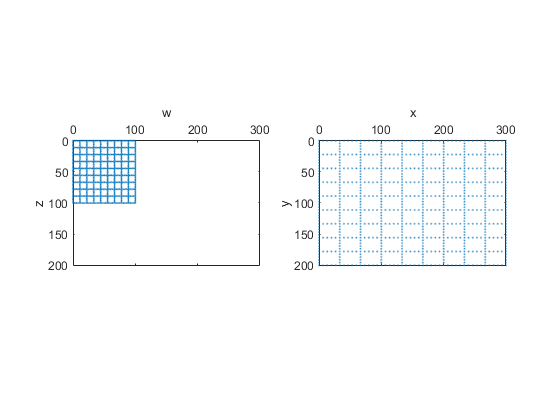

vistform(tform1,pointgrid([0 0; 100 100]));

%figure, vistform(tform2,pointgrid([0 0; 100 100]));

## Afinni transformace

pomoci maketform('affine',T) nebo tform = affine2d(T)

%afinni transformace odpovidajici tform1
T1 = [3 0 0; 
      0 2 0; 
      0 0 1];

tform3 = maketform('affine',T1);
WZ = [1 1; 
      3 2];
XY = tformfwd(WZ,tform3)

XY =      3     2
     9     4



WZ2 = tforminv(XY,tform3)

WZ2 =      1     1
     3     2


## UKOL 2

Jak vypada afinni matice odpovidajici tform2

%T2 = ..... doplnte
% tform4 = maketform('affine',T2);

% porovnejte s vysledky pro tform2
% WZ = [1 1; 3 2];
% XY = tformfwd(WZ,tform4)
% WZ2 = tforminv(XY,tform4)

## Afinni tranformace - otoceni

vizualizace

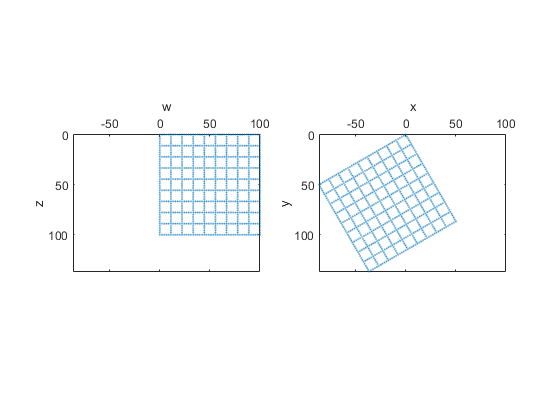

uhel = pi/3;
T = [cos(uhel) sin(uhel) 0; 
    -sin(uhel) cos(uhel) 0; 
    0 0 1];
tform5 = maketform('affine',T);

vistform(tform5,pointgrid([0 0; 100 100]));

## Aplikace tranformace na obrazky

g = imtransform(f,tform); nebo g = imwarp(f,tform);

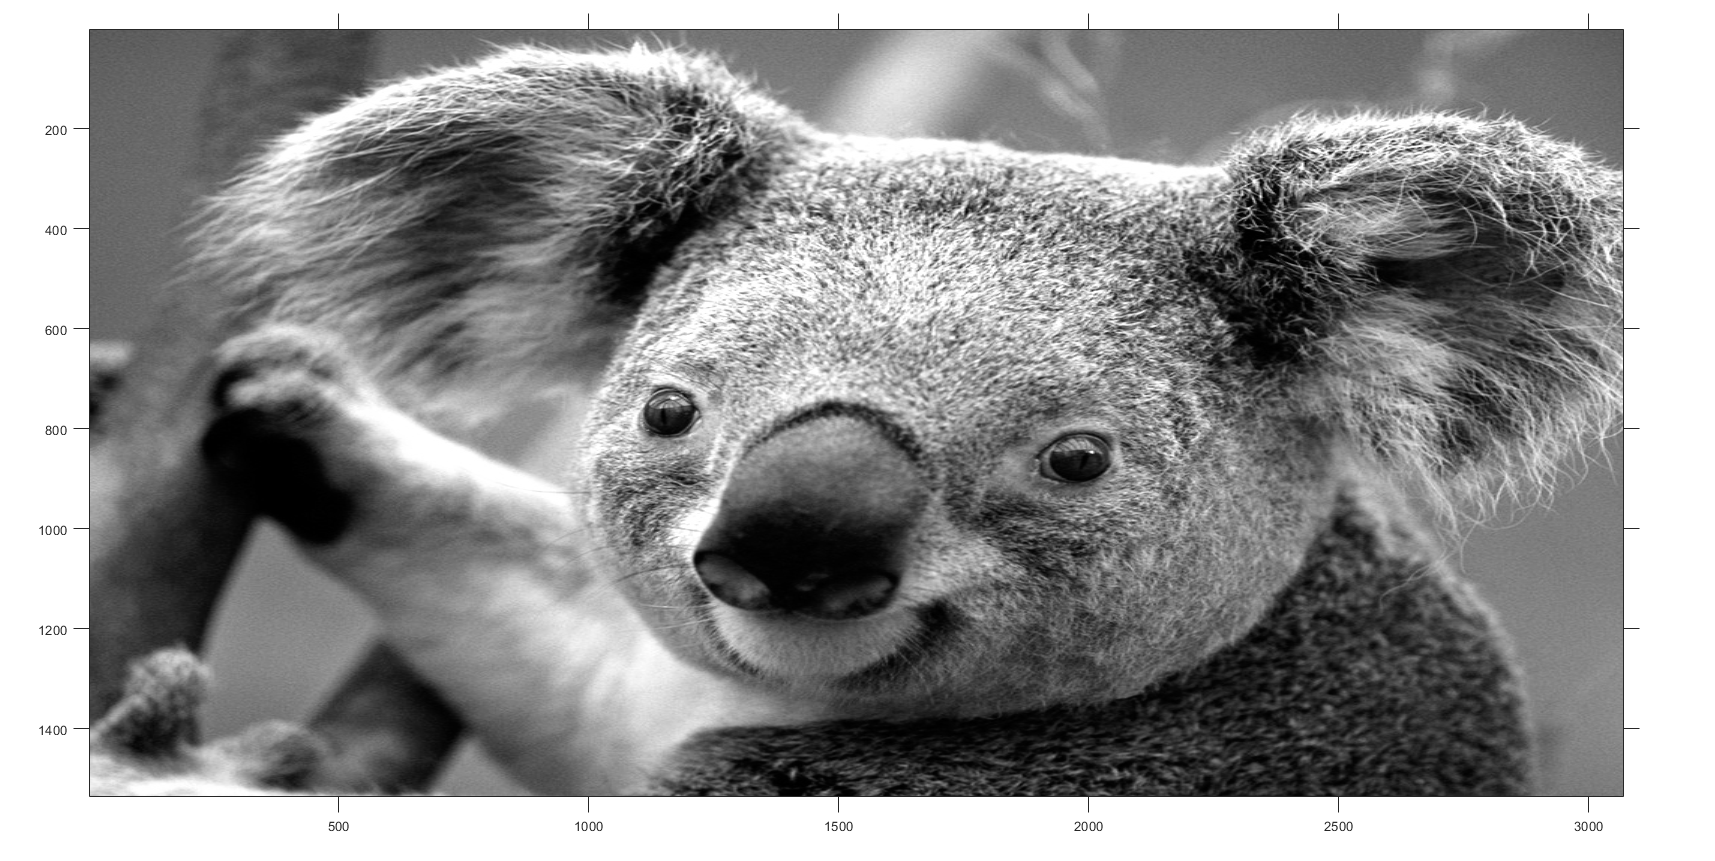

f = imread('picture1.png');

g1 = imtransform(f,tform1,'bilinear');
%g2 = imtransform(f,tform2);
%g3 = imtransform(f,tform3);
%g4 = imtransform(f,tform4);
g5 = imtransform(f,tform5);

figure,
imshow(g1);
axis on;

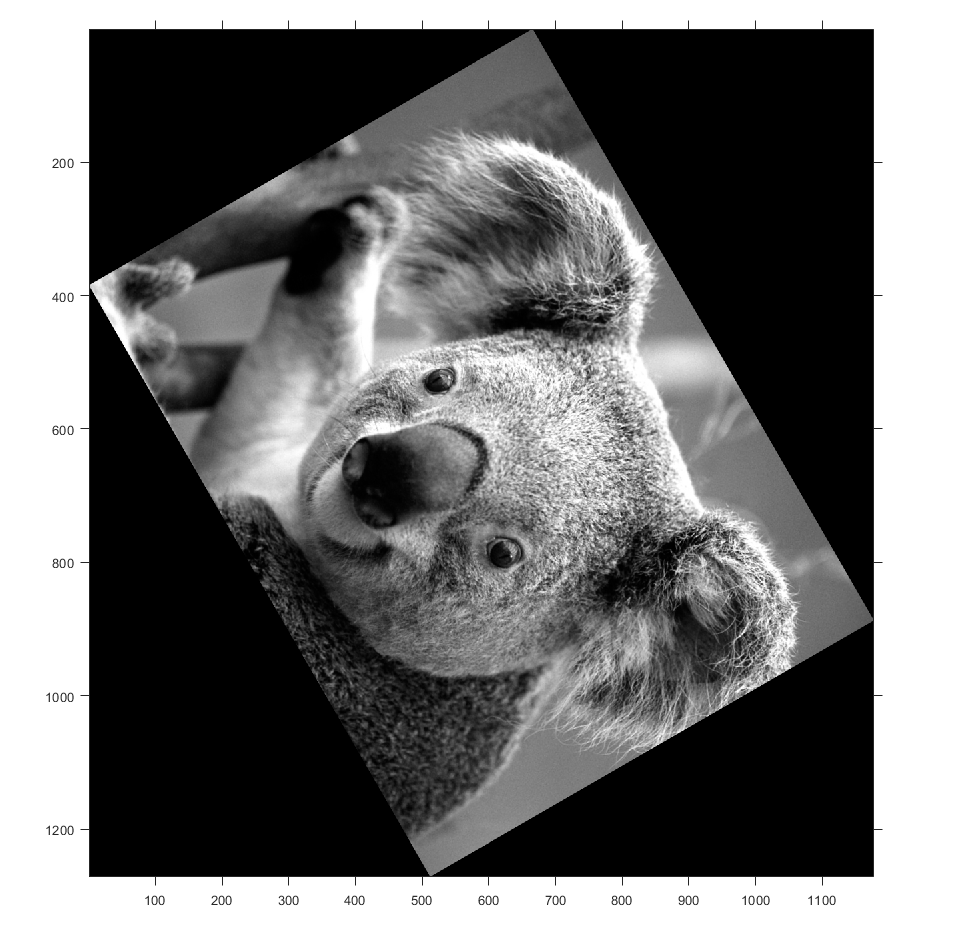


figure,
imshow(g5);
axis on;

## Matlab transformace

%imtranslate, imrotate

### Posunuti

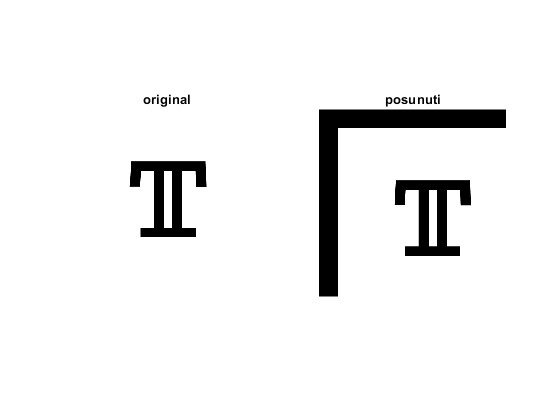

T = imread('t.png');
T2 = imtranslate(T, [50,50]);

figure
subplot(1,2,1)
imshow(T)
title('original')
subplot(1,2,2)
imshow(T2)
title('posunuti')

### Otoceni

T2 = imrotate(T, 30);

figure
subplot(1,2,1)
imshow(T)
title('original')
subplot(1,2,2)
imshow(T2)
title('otoceni')

### Zmena meritka

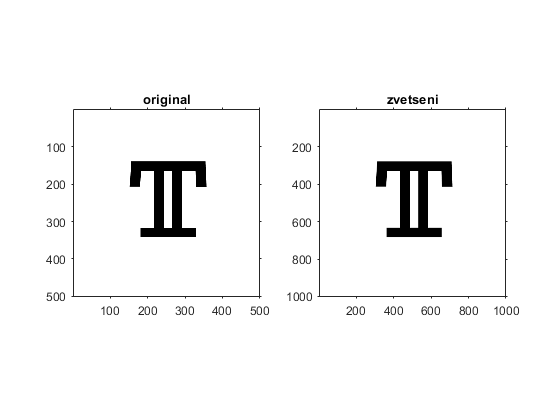

T2 = imresize(T, 2);

figure
subplot(1,2,1)
imshow(T)
title('original')
axis on
subplot(1,2,2)
imshow(T2)
title('zvetseni')
axis on

## Interpolace

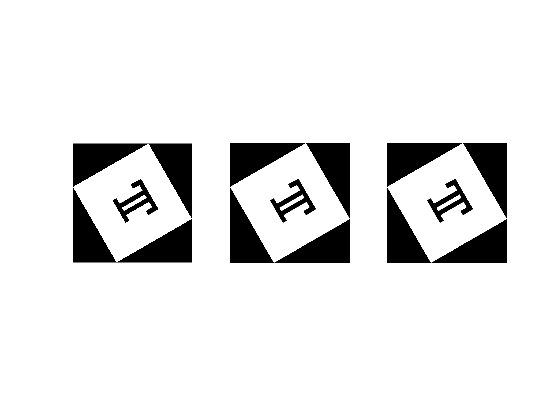

g5a = imtransform(T,tform5, 'nearest');
g5b = imtransform(T,tform5, 'bilinear');
g5c = imtransform(T,tform5, 'bicubic');

figure,
subplot(1,3,1), imshow(g5a);
subplot(1,3,2), imshow(g5b);
subplot(1,3,3), imshow(g5c);

## Registrace

Nacteni obrazku a vytvoreni noveho pomoci afinni trnasformace

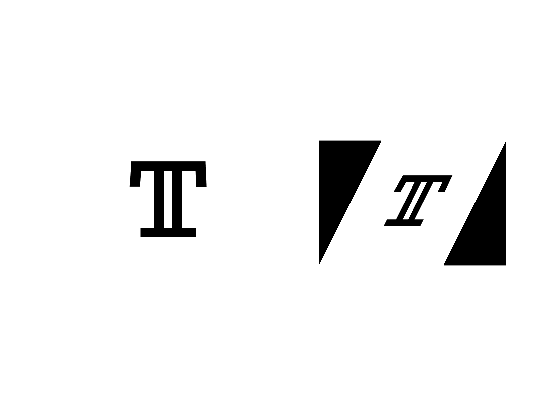

T = imread('t.png');
tform = affine2d([1 0 0; -0.5 1 0; 0 0 1]);

T2 = imwarp(T,tform);

figure
subplot(1,2,1)
imshow(T)
subplot(1,2,2)
imshow(T2)

### vyber kontrolnich bodu

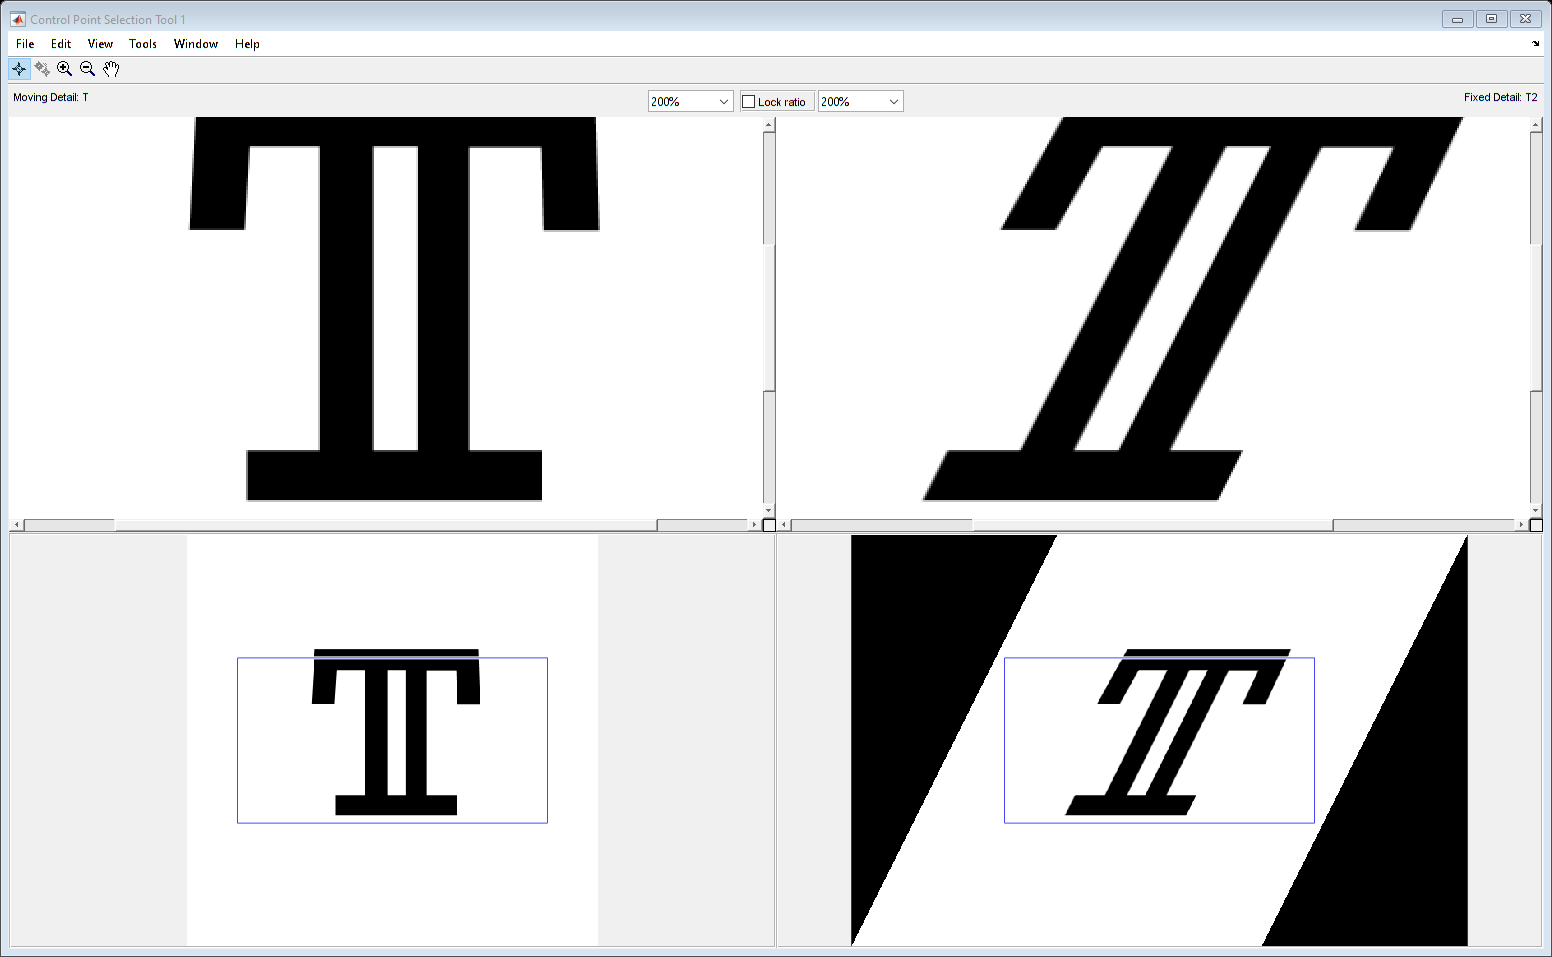

cpselect(T,T2);

### hledani transformace

tform2 = fitgeotrans(movingPoints,fixedPoints,'affine')

tform2 =   affine2d with properties:

                 T: [3×3 double]
    Dimensionality: 2


### Aplikace nalezene transformace

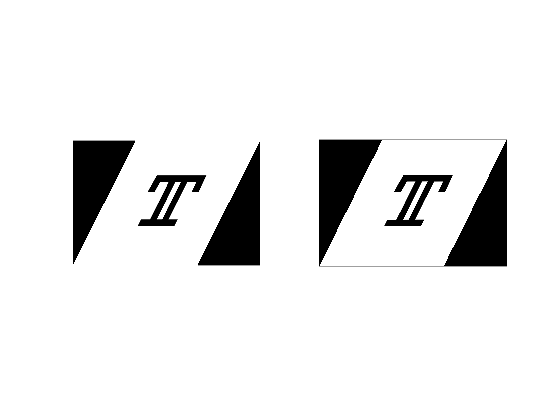

T3 = imwarp(T,tform2);
figure
subplot(1,2,1)
imshow(T2)
subplot(1,2,2)
imshow(T3)

## UKOL 3

Naprogramujte funkci registrace, ktera jako vstup bere 2 obrazky, ktere obsahuji cerny obdelnik (obdelnik1.png a obdelnik2.png) . Předpokladejme, ze obdelniky na obou obrazcich jsou ty same, jen druhy obdelnik je posunuty a deformovany operaci zvetseni/zmenseni v osach x a y. Funkce vraci 3 hodnoty – vektor posunutí a 2 koeficienty predstavujíci miru zvetseni/zmensení v ose x a v ose y.

% Pro nasledujici matice by byl vystup posunuti = [2,1], zvetseni_x = 1.5,
% zvetseni_y = 2

M1 = [ 1 1 1 1 1 1;
       1 0 0 1 1 1;
       1 0 0 1 1 1;
       1 1 1 1 1 1;
       1 1 1 1 1 1;
       1 1 1 1 1 1];
        
M2 = [ 1 1 1 1 1 1;
       1 1 1 1 1 1;
       1 1 1 0 0 0;
       1 1 1 0 0 0;
       1 1 1 0 0 0;
       1 1 1 0 0 0];

## Úpravy obrazu

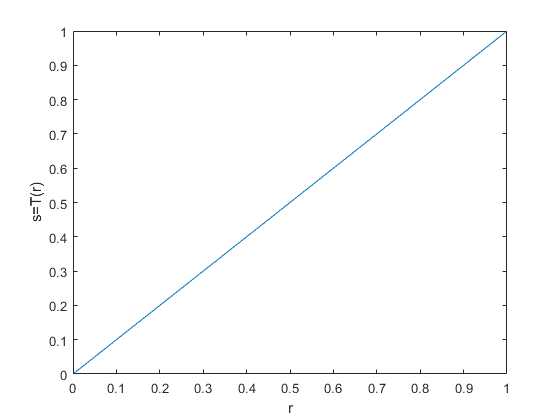

% g(x,y) = T[t(x,y)]
%f ... vstupní obrázek
%g ... výstupní obrázek
% T operátor definovaný na okolí bodu (x,z)

% Okolí 1x1 - single pixel operations
% T - transformace barev
% s = T(r)

figure,
r = (0:255)/255;
plot(r,r);
xlabel('r');
ylabel('s=T(r)');
xlim([0,1]);

### Zmena jasu

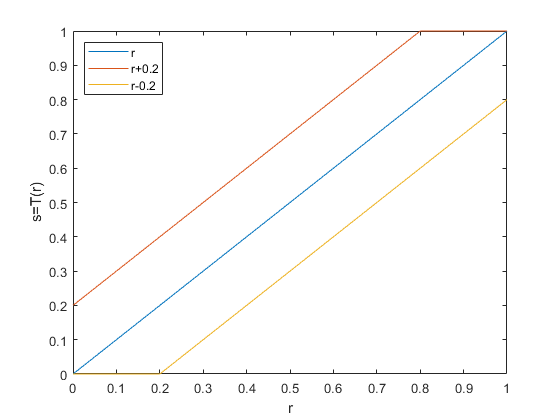

f = imread('picture1.png');
k1= 0.2;
k2 = -0.2;

s1 = clipMap(r + k1,0,1);
s2 = clipMap(r + k2,0,1);

figure,
plot(r,r);
xlabel('r');
ylabel('s=T(r)');
xlim([0,1]);
hold on;
plot(r,s1);
plot(r,s2);
legend('r','r+0.2','r-0.2','Location','northwest');

#### Aplikace zmeny jasu

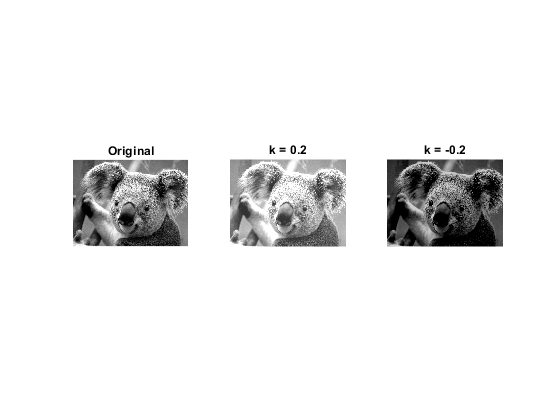

map1 = createMap(s1);
map2 = createMap(s2);

figure
subplot(1,3,1)
imshow(f)
title('Original')
subplot(1,3,2)
imshow(f,map1)
title('k = 0.2')
subplot(1,3,3)
imshow(f,map2)
title('k = -0.2')

#### Aplikace na kazdy pixel

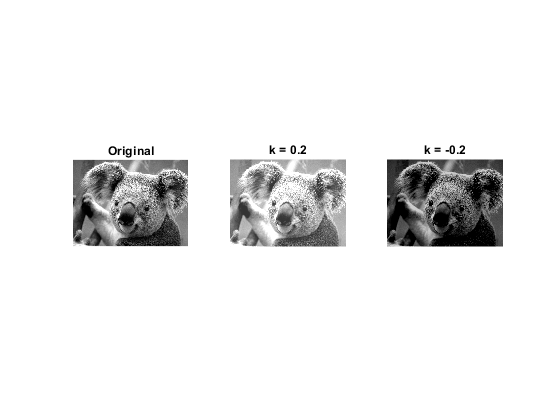

g1 = im2double(f) + k1;
g2 = im2double(f) + k2;

figure
subplot(1,3,1)
imshow(f)
title('Original')
subplot(1,3,2)
imshow(g1)
title('k = 0.2')
subplot(1,3,3)
imshow(g2)
title('k = -0.2')

### Zmena kontrastu

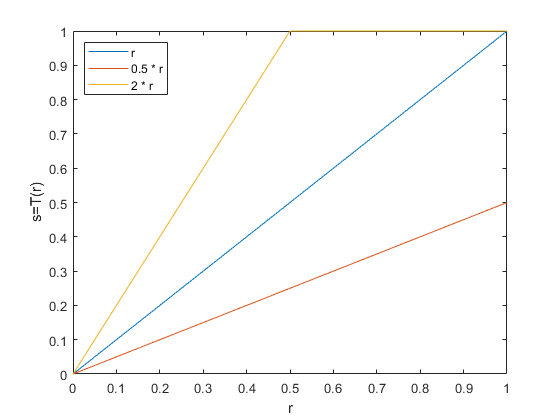

c1 = 0.5;
c2 = 2;

s3 = clipMap(c1*r,0,1);
s4 = clipMap(c2*r,0,1);

figure,
plot(r,r);
xlabel('r');
ylabel('s=T(r)');
xlim([0,1]);
hold on;
plot(r,s3);
plot(r,s4);
legend('r','0.5 * r','2 * r','Location','northwest');

#### Aplikace zmeny kontrastu

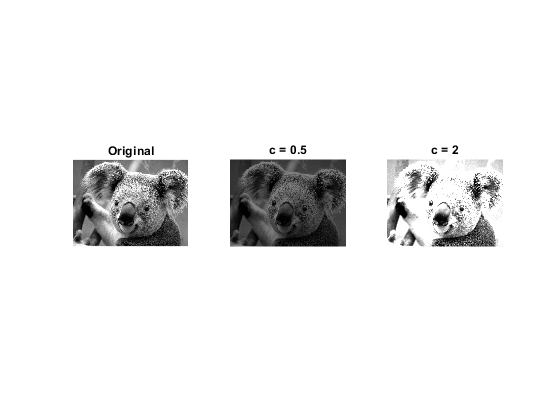

map3 = createMap(s3);
map4 = createMap(s4);

figure
subplot(1,3,1)
imshow(f)
title('Original')
subplot(1,3,2)
imshow(f,map3)
title('c = 0.5')
subplot(1,3,3)
imshow(f,map4)
title('c = 2')

### Roztazeni kontrastu

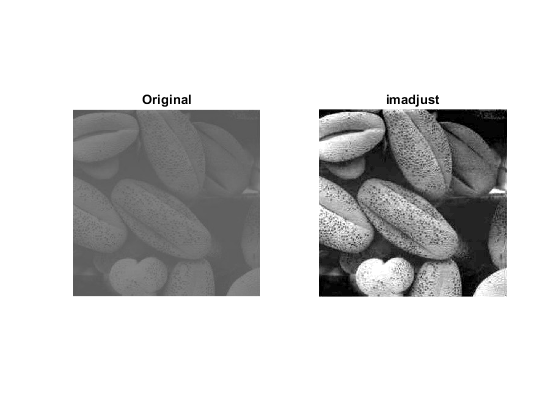

%imadjust
I = imread('pic1.png');
J = imadjust(I);

figure
subplot(1,2,1)
imshow(I);
title('Original')
subplot(1,2,2)
imshow(J);
title('imadjust')

### Negativ obrazku

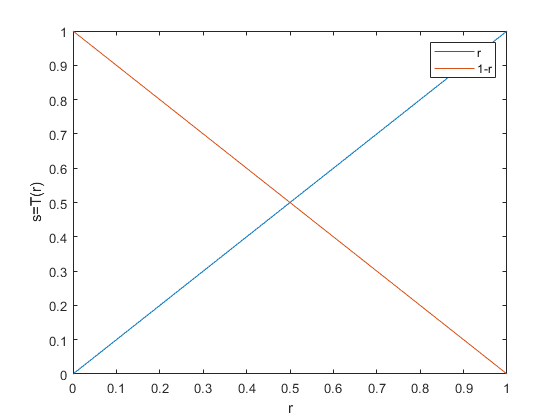

% f = rgb2gray(imread('mamogram.jpg'));
% neg = 255 - I; 
% neg = imcomplement(I);

figure,
s5 = 1-r;
plot(r,r);
xlabel('r');
ylabel('s=T(r)');
xlim([0,1]);
hold on;
plot(r,s5);
legend('r','1-r','Location','northeast');

#### Aplikace negativu

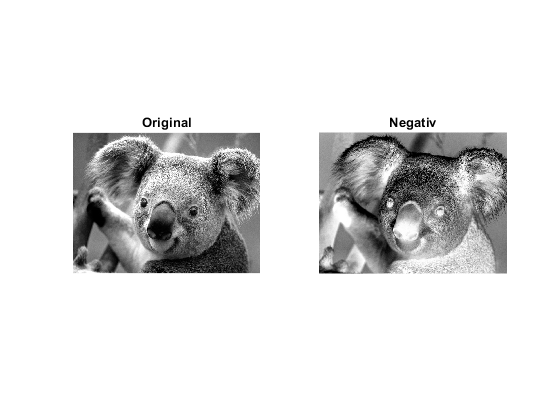

map5 = createMap(s5);

figure
subplot(1,2,1)
imshow(f)
title('Original')
subplot(1,2,2)
imshow(f,map5)
title('Negativ')

### Logaritmicka transformace

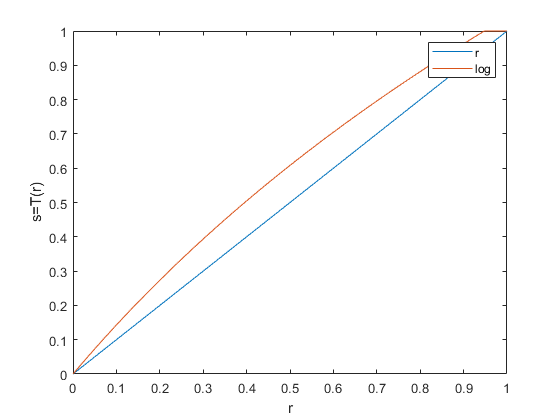

c = 1.5;
s6 = clipMap(c*log(1+r),0,1);

figure,
plot(r,r);
xlabel('r');
ylabel('s=T(r)');
xlim([0,1]);
hold on;
plot(r,s6);
legend('r','log','Location','northeast');

### Gamma transformace

#### Gamma < 1

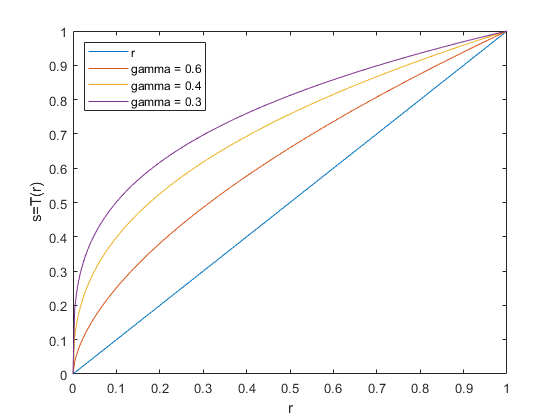

f=rgb2gray(imread('spine.png'));
c=1;
Gamma=[0.6 0.4 0.3];

%x1=double(x); 
% y=c*(x1.^Gamma(1));                             % s=c*(r^ ?)
% y1=c*(x1.^Gamma(2));
% y2=c*(x1.^Gamma(3));

s7 = clipMap(c*(r.^Gamma(1)),0,1);
s8 = clipMap(c*(r.^Gamma(2)),0,1);
s9 = clipMap(c*(r.^Gamma(3)),0,1);

figure,
plot(r,r);
xlabel('r');
ylabel('s=T(r)');
xlim([0,1]);
hold on;
plot(r,s7);
plot(r,s8);
plot(r,s9);
legend('r','gamma = 0.6','gamma = 0.4','gamma = 0.3','Location','northwest');

#### Aplikace na obrazek

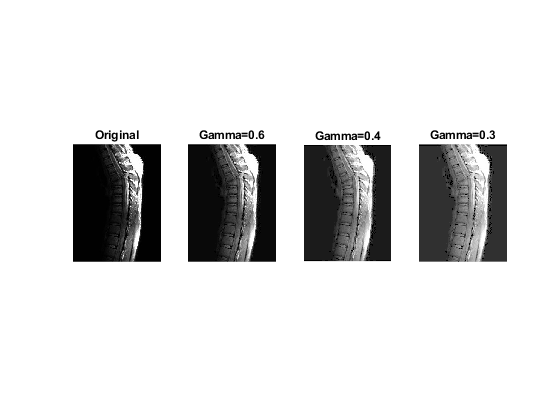

map7 = createMap(s7);
map8 = createMap(s8);
map9 = createMap(s9);

figure
subplot(1,4,1)
imshow(f)
title('Original')
subplot(1,4,2)
imshow(f,map7)
 title('Gamma=0.6')
subplot(1,4,3)
imshow(f,map8)
 title('Gamma=0.4')
 subplot(1,4,4)
imshow(f,map9)
title('Gamma=0.3')

#### Gamma > 1

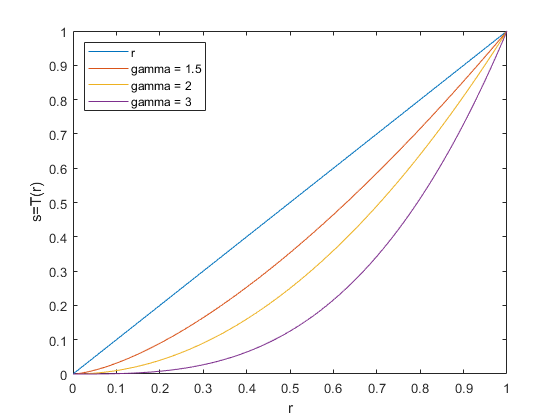

f = rgb2gray(imread('vase.jpg'));
c=1;
Gamma=[1.5 2 3];

%x1=double(x); 
% y=c*(x1.^Gamma(1));                             % s=c*(r^ ?)
% y1=c*(x1.^Gamma(2));
% y2=c*(x1.^Gamma(3));

s10 = clipMap(c*(r.^Gamma(1)),0,1);
s11 = clipMap(c*(r.^Gamma(2)),0,1);
s12 = clipMap(c*(r.^Gamma(3)),0,1);

figure,
plot(r,r);
xlabel('r');
ylabel('s=T(r)');
xlim([0,1]);
hold on;
plot(r,s10);
plot(r,s11);
plot(r,s12);
legend('r','gamma = 1.5','gamma = 2','gamma = 3','Location','northwest');

#### Aplikace na obrazek

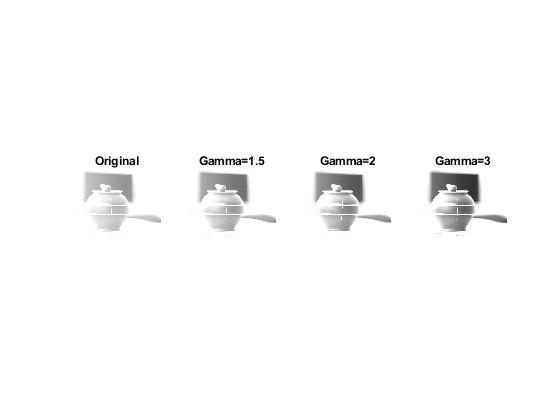

map10 = createMap(s10);
map11 = createMap(s11);
map12 = createMap(s12);

figure
subplot(1,4,1)
imshow(f)
title('Original')
subplot(1,4,2)
imshow(f,map10)
 title('Gamma=1.5')
subplot(1,4,3)
imshow(f,map11)
 title('Gamma=2')
 subplot(1,4,4)
imshow(f,map12)
title('Gamma=3')

### Intensity-level slicing

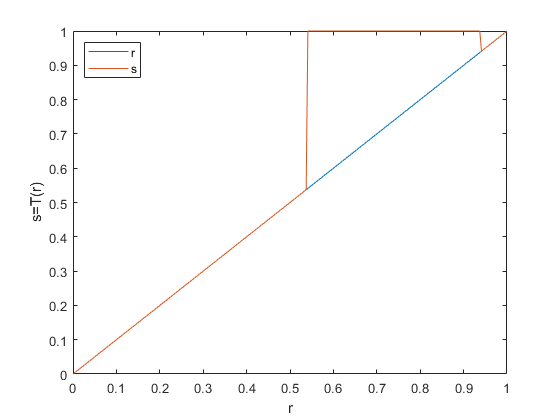

f = rgb2gray(imread('aorta.png'));
%J = I;
%J(J >= 140 & J<=240) = 255;

r1 = 0.54;
r2 = 0.94;

s13 = r;
s13(s13 >= r1 & s13<=r2) = 1;

figure,
plot(r,r);
xlabel('r');
ylabel('s=T(r)');
xlim([0,1]);
hold on;
plot(r,s13);
legend('r','s','Location','northwest');

#### Aplikace na obrazek

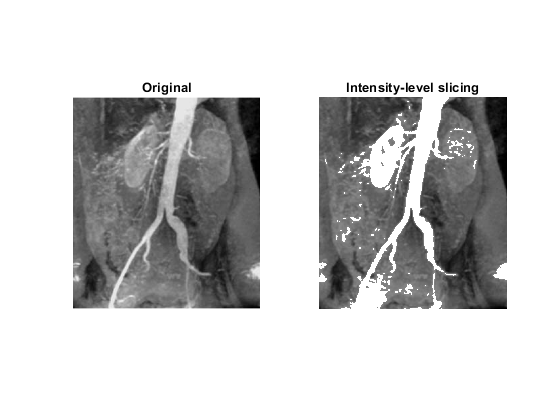

map13 = createMap(s13);

figure
subplot(1,2,1)
imshow(f);
title('Original')
subplot(1,2,2)
imshow(f,map13);
title('Intensity-level slicing')

### Bit-level slicing

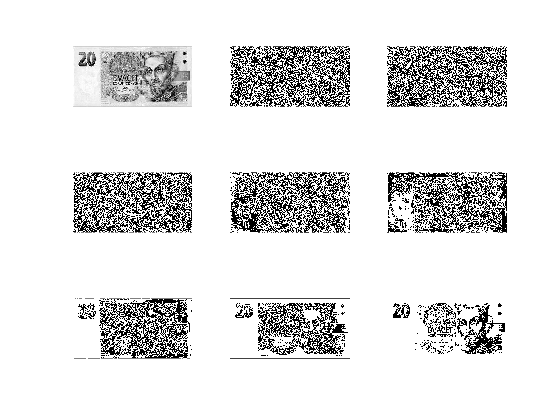

I = imadjust(rgb2gray(imread('koruna.png')));

I1 = bitand(I,1);
I2 = bitand(I,2);
I3 = bitand(I,4);
I4 = bitand(I,8);
I5 = bitand(I,16);
I6 = bitand(I,32);
I7 = bitand(I,64);
I8 = bitand(I,128);

figure
subplot(3,3,1)
imshow(I,[])
subplot(3,3,2)
imshow(I1,[])
subplot(3,3,3)
imshow(I2,[])
subplot(3,3,4)
imshow(I3,[])
subplot(3,3,5)
imshow(I4,[])
subplot(3,3,6)
imshow(I5,[])
subplot(3,3,7)
imshow(I6,[])
subplot(3,3,8)
imshow(I7,[])
subplot(3,3,9)
imshow(I8,[])

#### Skladani obrazku

J1 = I8 + I7;
J2 = I8 + I7 +I6;
J3 = I8 + I7 +I6 + I5;

subplot(1,3,1)
imshow(J1);
subplot(1,3,2)
imshow(J2);
subplot(1,3,3)
imshow(J3);

## UKOL k zamysleni

jakym zpusobem se zmeni histogram obrazku, pri provedeni techto operaci:

- zmena jasu

- zmena kontrastu

- negativ obrazku

- gamma korekce s hodnotou < 1

- gamma korekce s hodnotou > 1